#### Load data

Eidors Toolbox must be loaded.

data_X (measurements), data_Y (images as vectors)

load('trainData.mat')

#### Set aside 4000 of the images for network validation and test

clear data_Xval data_Yval
idx = randperm(size(data_X,1),4000);
data_Xval = data_X(idx,:);
data_X(idx,:) = [];
data_Yval = data_Y(idx,:);
data_Y(idx,:) = [];
clear idx

#### Train network

Setting parameters:

inputSize = 120; % measurenet vector
outputSize = 2811; % images resolution

Transforming input variables (testing and validation) from matrix to cell type:

x_cell = num2cell(data_X',[1,inputSize])';
x_cell_val = num2cell(data_Xval',[1,inputSize])';

numHiddenUnits = 2048; % number of hidden units

CNN+LSTM network architecture:

layers = [
    sequenceInputLayer(inputSize,"Name","sequence")
    convolution1dLayer(3,64,"Name","conv1d_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1") 
    dropoutLayer(0.2,'Name','drop1')
    convolution1dLayer(3,128,"Name","conv1d_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2") 
    dropoutLayer(0.2,'Name','drop2')
    lstmLayer(numHiddenUnits,'OutputMode','sequence','Name','lstm_1')
    dropoutLayer(0.2,'Name','drop_lstm_1')
    lstmLayer(numHiddenUnits,'OutputMode','last','Name','lstm_2')
    dropoutLayer(0.2,'Name','drop_lstm_2')
    fullyConnectedLayer(outputSize,"Name","fc")
    regressionLayer("Name","regressionoutput")];


Training options:

maxEpochs = 5000;   % number of epochs
miniBatchSize = 64; % minibatch size

options = trainingOptions('adam', ...
    'ExecutionEnvironment','auto', ...
    'MaxEpochs',maxEpochs, ...
    'ValidationData',{x_cell_val,data_Yval}, ...
    'ValidationFrequency',100, ...
    'ValidationPatience',20, ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate', 0.001, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.2, ...
    'LearnRateDropPeriod',5, ...
    'SequenceLength','longest', ...
    'Shuffle','every-epoch', ...
    'Verbose',0, ...
    'Plots','training-progress');

Train network:

[netCNN_LSTM, info] = trainNetwork(x_cell,data_Y,layers,options);


Alternatively, upload a pre-trained neural network.

Uncomment (remove "%") if necessary.

% load('netCNN_LSTM.mat');

## Simulated reconstruction

Load FEM mesh of the head model

load('tank_head_2023_2D_v1_EIDORS.mat');

Run startup.m script of Eidors toolbox ([https://eidors3d.sourceforge.net/download.shtml](https://eidors3d.sourceforge.net/download.shtml))

% startup

Create images

valSize is the total number of validation ceses

valSize = size(data_Xval,1)

If you don't want to generate 4000 images and stop after generating, e.g. 10 pairs of images, set valSize = 10.

Otherwise, please comment on this line.

valSize = 10

Start the loop of images:

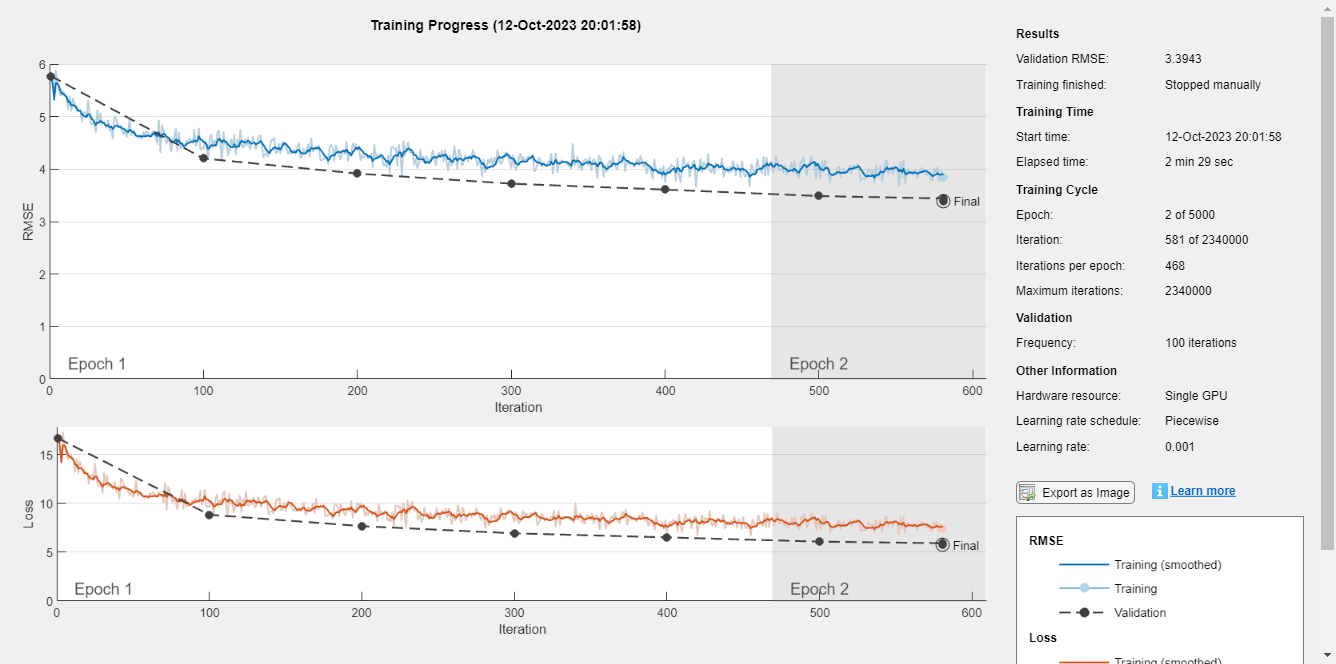

for i= 1 : valSize
    % reconstruction creation
    imagePred = predict(netCNN_LSTM,x_cell_val(i)); 

    % figure creation
    figure;

    
    % reconstruction visualization
    subplot(1,2,1);  % Arguments indicate 1 row, 2 columns, and position 1
    img.elem_data = imagePred;
    h = show_fem(img,1); % Create a handle h for the patch object created by show_fem
    set(h, 'EdgeAlpha', 0.1); % Set the transparency of the mesh
    xlabel('(mm)'); zlabel('(mm)'); ylabel('(mm)');
    title('Reconstruction');
    % pattern image visualization   
    subplot(1,2,2);  % Arguments indicate 1 row, 2 columns, and position 2
    img.elem_data = data_Yval(i,:);
    show_fem(img,1);
    h = show_fem(img,1);
    set(h, 'EdgeAlpha', 0.1);

valSize = 4000

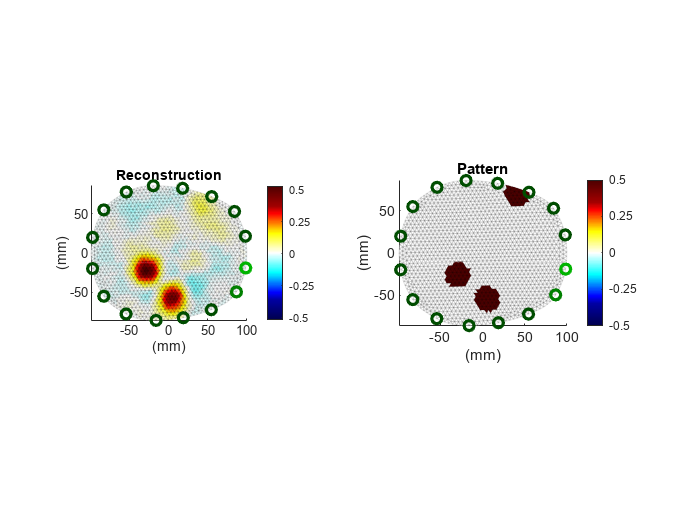

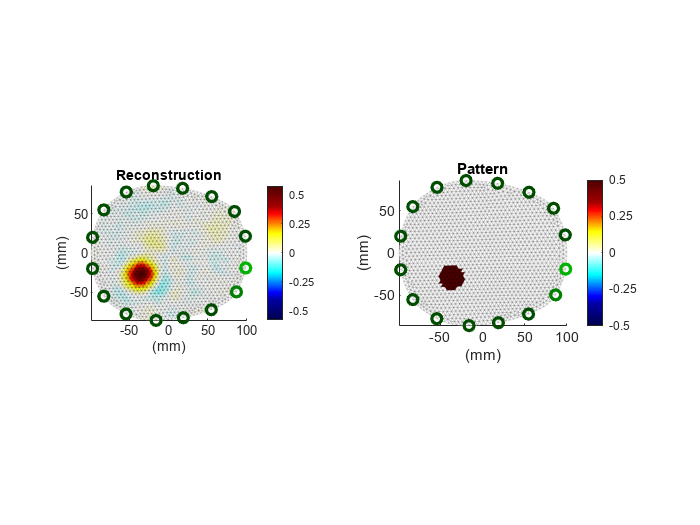

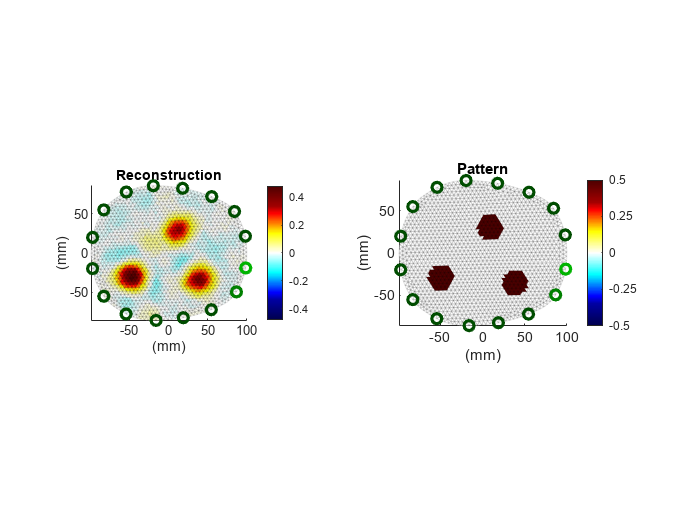

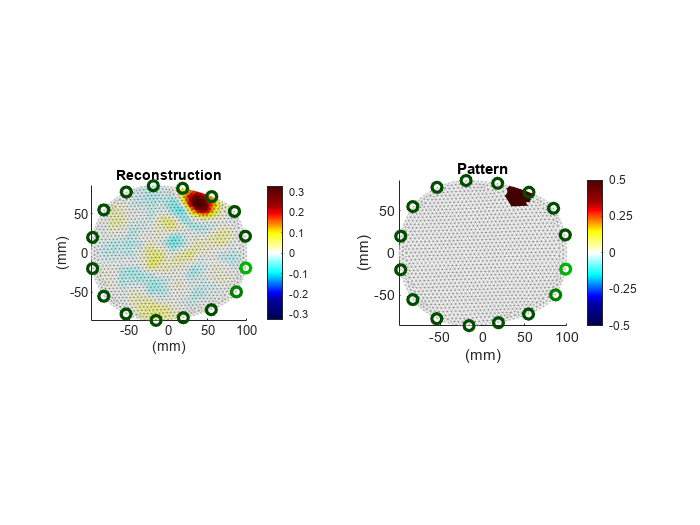

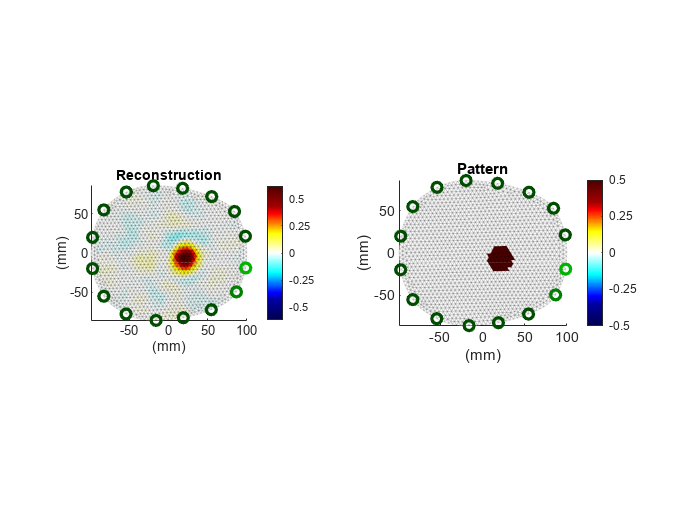

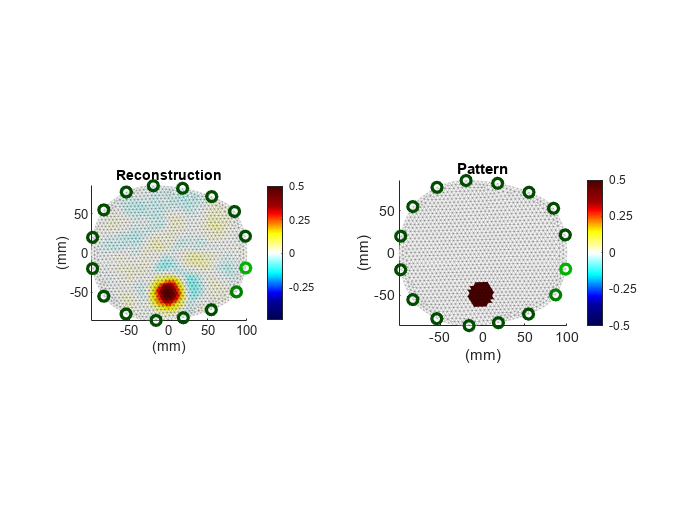

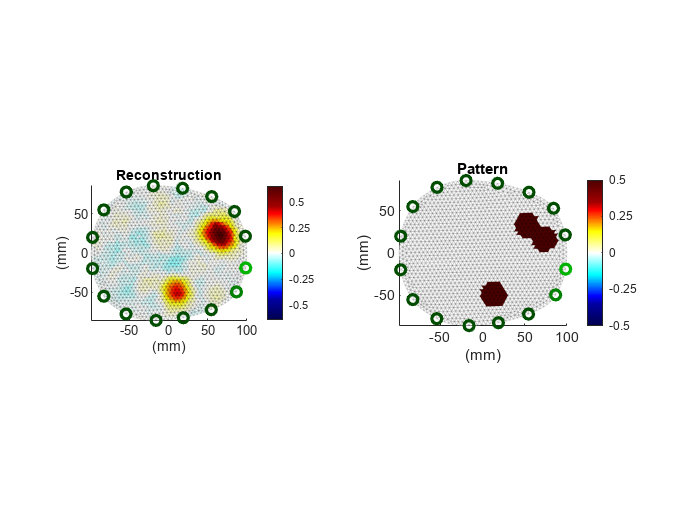

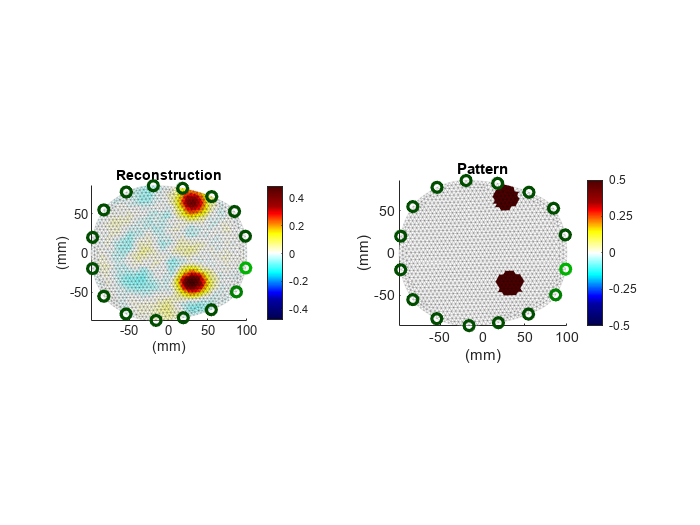

    xlabel('(mm)'); zlabel('(mm)'); ylabel('(mm)');
    title('Pattern');

    pause(2); % pause for 2 second
end




